% generate figure 2CDEFGH
% dependence: initRSG2prior, v2struct, applytofig

### set up

S=initRSG2prior;
v2struct(S); % behDir animalNm nAnimal

### main loop

H


EyeRight


EyeLeft


HandRight


HandLeft


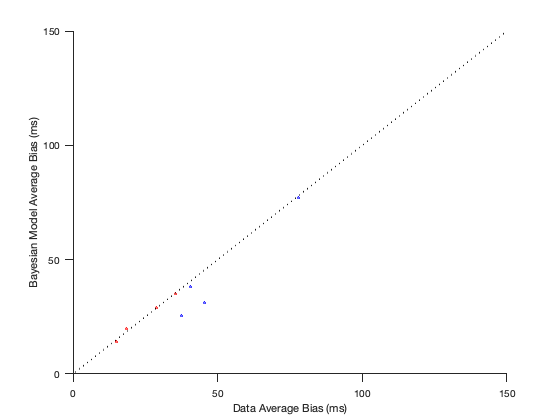

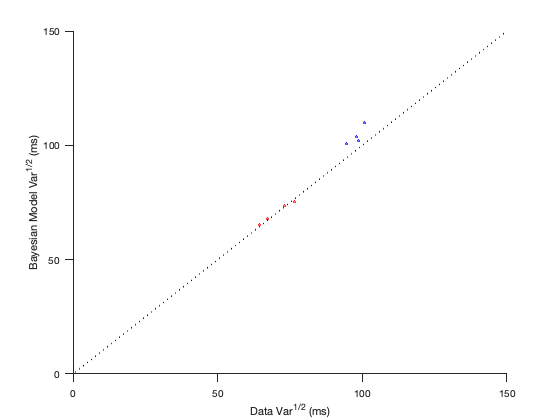

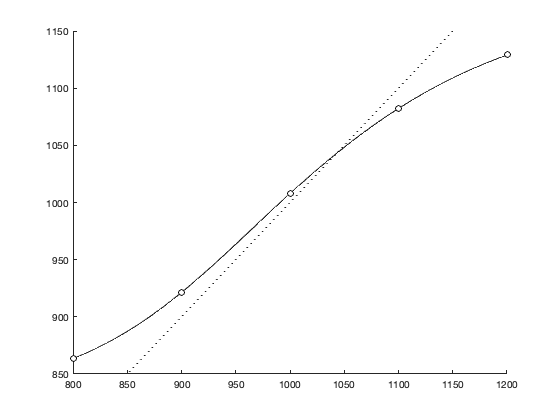

# trials: 309, 85


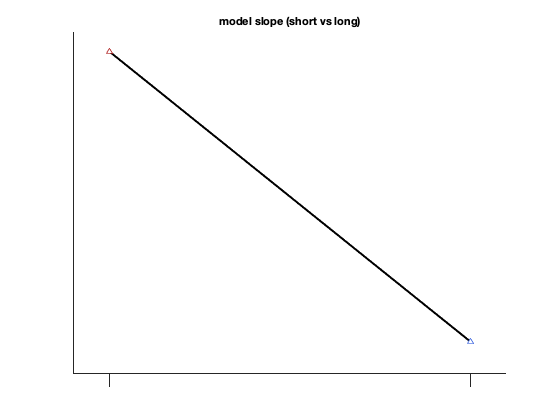

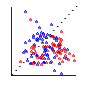

short: 3.77e-10
long: 0.00137


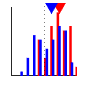

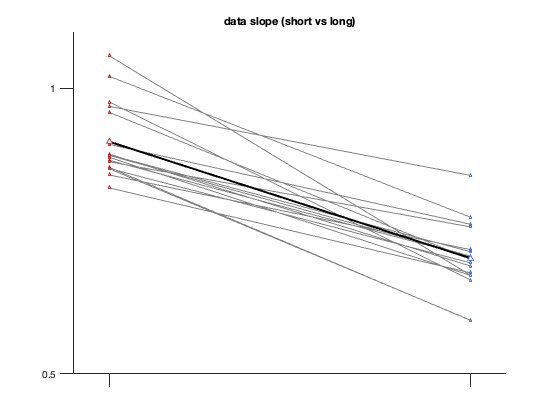

signrank test ignoring conditions
H0(slope(short)<1): 0.00022892
H0(slope(long)<1): 3.9067e-13
H0(slope(short)>0): 3.9067e-13
H0(slope(long)>0): 3.9067e-13
H0(slope(long)<slope(short)): 1.5215e-11


G


EyeRight


EyeLeft


HandRight


HandLeft


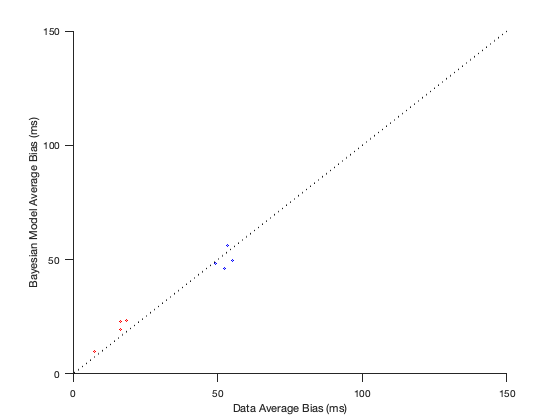

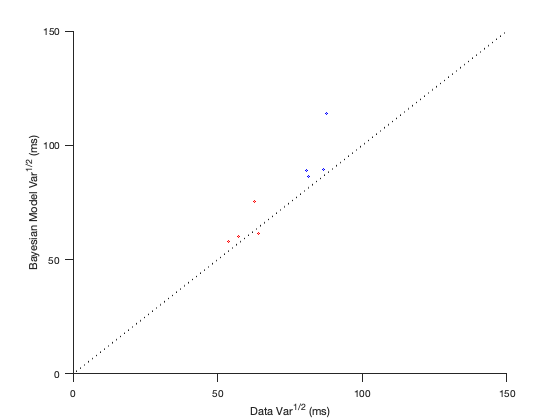

# trials: 511, 139


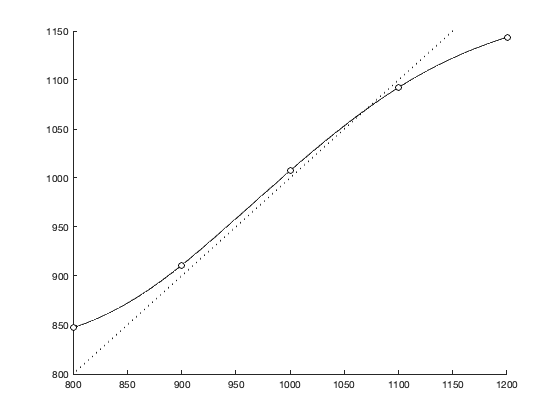

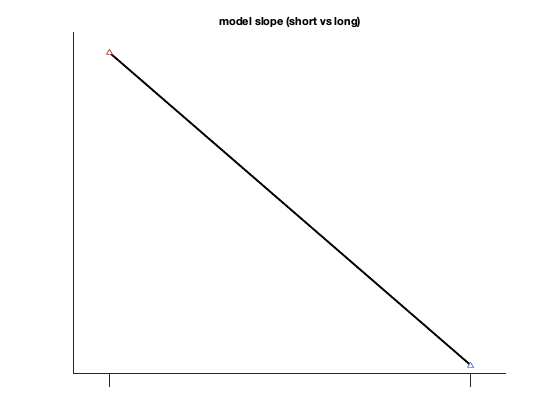

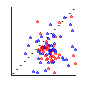

short: 5.77e-08
long: 9.96e-07


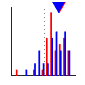

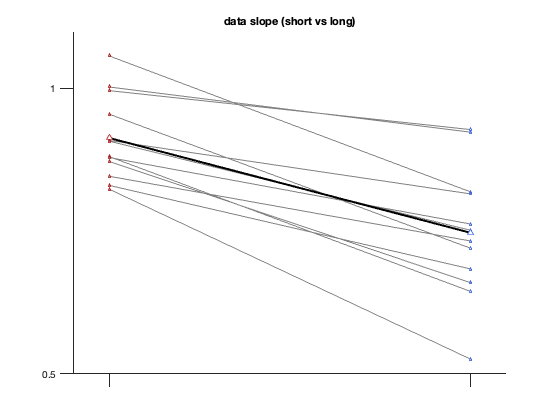

signrank test ignoring conditions
H0(slope(short)<1): 9.2557e-05
H0(slope(long)<1): 1.7886e-09
H0(slope(short)>0): 8.4179e-10
H0(slope(long)>0): 8.4179e-10
H0(slope(long)<slope(short)): 5.3477e-09


for i=1:nAnimal
    disp('=========');
    disp(animalNm{i});
    disp('=========');
    id=animalNm{i};
    tmp=load(fullfile(behDir,[ id '_RSGprior_DMFC.mat']));
    tmp.iAnimal=i;
    
    plot_2CDEG(S,tmp); % predicted (bias/var) vs data (bias/var); model's tp vs ts & slope(short) vs slope(long)
    
    plot_2F(S,tmp); % delta tp(extreme) vs delta tp (middle) + difference histogram
    
    plot_2H(S,tmp); % slope(short) vs slope(long)
    drawnow; pause(0.5);
end

## subfunction for each animal

### figure2CD: predicted (bias/var) vs data (bias/var); model's tp vs ts & slope(short) vs slope(long)

function plot_2CDEG(S,tmp)

v2struct(S);
v2struct(tmp);

% simulation BLS nSim times and average them
nSim=500;
nRep=1; % 50 times more trials than data: now condition-specific, 1600 trials/40 cond: 40 trials/cond

% plot
lw=0.5;
ms=2;
tmpMarker={'s','d';'o','^'}; % eyeRight, eyeLeft; handRight, handLeft

%% main
iFig=1;

if iAnimal==1
    tmpMarker2='^';
else
    tmpMarker2='o';
end
h2=figure; ha; % predicted (bias) vs data (bias)
h3=figure;  ha; % predicted (var) vs data (var)

for j=1:nEH
    for k=1:nTarg
        disp([ehNm{j} targNm{k}]);
        
        wm=wFitCond(j,k).w_m;
        wp=wFitCond(j,k).w_p;
        bL=wFitCond(j,k).offset1;
        bS=wFitCond(j,k).offset2;
        
        %% simulation BLS nSim times and average them
        % do simulation & calculate mean/SD
        mutSim=nan(nPr,nTspp,nSim); % mean [2priors x 5ts/pr x #simulation]
        sdtSim=nan(nPr,nTspp,nSim); % SD  [2priors x 5ts/pr x #simulation]
        rmsBiasSim=nan(nPr,nSim); % mean Bias  [2priors x #simulation]
        rmsVSim=nan(nPr,nSim); % mean sqrtVar  [2priors x #simulation]
        
        slopeSim=nan(nPr,nSim);
        for iSim=1:nSim
            for i=1:nPr % for each prior
                tmpId= idHandEye==(2-j) & theta==180*(k-1) & idShortTrial==(2-i) & ~idOut; % sessId==iS(jS) &
                tmpT=repmat(T(tmpId),nRep,1);
                
                % simulation
                offset=bS*(2-i)+bL*(i-1);
                tm=tmpT+wm*randn(size(tmpT)).*tmpT;
                te=BayesEst(tm,wm,[min(tmpT) max(tmpT)],'uniform')+offset;
                tpModel=te+wp*randn(size(te)).*te;
                
                % calculate mean/SD
                sdtModel=nan(size(tmpT));
                tmpTlist=unique(tmpT);
                for jT=1:nnz(tmpTlist)
                    id=(tmpT==tmpTlist(jT));
                    
                    mutSim(i,jT,iSim)=mean(tpModel(id));
                    sdtSim(i,jT,iSim)=std(tpModel(id));
                    
                    sdtModel(id)=std(tpModel(id));
                end
                
                LM=fitlm(tmpT,tpModel,'linear',...
                    'Weights',1./sdtModel);
                slopeSim(i,iSim)=table2array(LM.Coefficients(2,1));
                
                % prior-specific meanBias & sqrtVar
                rmsBiasSim(i,iSim)=sqrt(mean((mutSim(i,:,iSim)-tmpTlist(:)').^2));
                rmsVSim(i,iSim)=sqrt(mean((sdtSim(i,:,iSim)).^2));
            end % for i=1:nPr
        end % for iSim=1:nSim
        
        %% calculate mean and SD for each ts
        mut=nan(nPr,nTspp); % mean [2priors x 5ts/pr]
        sdt=nan(nPr,nTspp); % SD
        rmsBias=nan(nPr,1); % mean Bias [2priors x 1]
        rmsV=nan(nPr,1); % mean sqrtVar
        for i=1:nPr
            for iTs=1:length(Tmat{i})
                
                tmpId=idHandEye==(2-j) & theta==180*(k-1) & idShortTrial==(2-i) & T==Tmat{i}(iTs)  & ~idOut; % sessId==iS(jS) &
                
                mut(i,iTs)=mean(t(tmpId));
                sdt(i,iTs)=std(t(tmpId));
                
            end % for iTs=1:length(Tmat{i})
            
            % prior-specific meanBias & sqrtVar
            rmsBias(i)=sqrt(mean((mut(i,:)-Tmat{i}(:)').^2));
            rmsV(i)=sqrt(mean((sdt(i,:)).^2));
        end % i pr
        
        %% plot
        
        for i=1:nPr
            x1=rmsBias(i); % data
            y1=rmsV(i);
            % choose best
            tmpE=sqrt(((rmsBiasSim(i,:)-x1).^2)+((rmsVSim(i,:)-y1).^2));
            iBest=min(tmpE)==tmpE;
            x2=rmsBiasSim(i,iBest); % mean(rmsBiasSim(i,:)); % model
            y2=rmsVSim(i,iBest); % mean(rmsVSim(i,:));
            
            figure(h2); % data vs model
            plot(x1,x2,tmpMarker2,'color',pplot.cmap{(i-1)*2+1},'linewidth',lw,'markersize',ms,'markerfacecolor','w'); % bias
            drawnow;
            
            figure(h3); % data vs model
            plot(y1,y2,tmpMarker2,'color',pplot.cmap{(i-1)*2+1},'linewidth',lw,'markersize',ms,'markerfacecolor','w'); % var
            drawnow;
            
        end          % i pr
    end % for k=1:nTarg
end % for j=1:nEH

figure(h2); % data vs model
axis([0 150 0 150]);  % tight;
plotIdentity(gca);
set(gca,'xtick',0:50:250,'ytick',0:50:250,'tickdir','out','ticklength',[0.02 0.02]); xlabel('Data Average Bias (ms)');ylabel('Bayesian Model Average Bias (ms)');

figure(h3); % data vs model
axis([0 150 0 150]);  % tight;
plotIdentity(gca);
set(gca,'xtick',0:50:250,'ytick',0:50:250,'tickdir','out','ticklength',[0.02 0.02]); xlabel('Data Var^1^/^2 (ms)');ylabel('Bayesian Model Var^1^/^2 (ms)');

%% % model tp vs ts
figure; ha;
% choose one specific condition
tm=[min(Tmat{2}):max(Tmat{2})]';
te=BLS(tm,wFitCond(2,2).w_m,[min(Tmat{2}) max(Tmat{2})],'uniform');
plot(tm,te,'k-');
te2=BLS(Tmat{2},wFitCond(2,2).w_m,[min(Tmat{2}) max(Tmat{2})],'uniform');
plot(Tmat{2},te2,'ko','markerfacecolor','w')
plotIdentity(gca);
drawnow;

%%  model slope (short vs long)
figure; ha; %
msize=5;
sS=slopeSim(1,:);
sL=slopeSim(2,:);

% plot([1;2],[sS(:)'; sL(:)'],'-','color',[.5 .5 .5],'linewidth',.5); % connecting lines
% plot(1,sS(:),'^','color',tmpCmap{1,1}(1,:),'markersize',msize/2); % individual points
% plot(2,sL(:),'^','color',tmpCmap{2,1}(1,:),'markersize',msize/2);
plot([1;2],mean([sS(:)'; sL(:)'],2),'k-','linewidth',2); % connecting lines
plot(1,mean(sS(:)),'^','markersize',msize,'markerfacecolor','w','color',tmpCmap{1,1}(1,:)); % individual points
plot(2,mean(sL(:)),'^','markersize',msize,'markerfacecolor','w','color',tmpCmap{2,1}(1,:));
set(gca,'xtick',1:2,'xticklabel',{[];[]},'ytick',0:.5:1,'xlim',[0.9 2.1],'tickdir','out','ticklength',[0.03 0.03]);
title('model slope (short vs long)');
drawnow;
end

function numValue = posteriorNum(s,m,wm)
%% This is the simplest version of the calculation.
%Does not allow the measurements to covary.

sigmaDet = ((s*wm).^2).^size(m,2);
numValue = 1./sqrt(2*pi*sigmaDet).*exp(-.5*sum((s-m).^2./(s*wm).^2,2));

end

function plotCircleHalf(h,radius,color)
% assuming x ranging from negative to positive
x=linspace(0,radius,100);
y=sqrt((radius^2)-(x.^2));
plot(x,y,':','color',color); hold on;
end

function estimate = BayesEst(...
    measurements, ...
    weberMeasure, ...
    priorParams,  ...
    prior)
%% Using Matlab's integral() function

%measurements must be a column vector of the measurement values
%
%weberMeasure is the Weber fraction of the measurement. Pass in one value
%or a column vector with length equal to measurements.
%
%priorParams defines the distribution. For a uniform prior this is the just
%the support (start and end). For a Gaussian prior it's the mean and
%variance.
%
%prior is the prior type. Leave blank for uniform.

wm = weberMeasure;
if numel(wm) == 1
    wm = repmat(wm,size(measurements,1),1);
end

if ~exist('prior','var') || isempty(prior)
    prior = 'uniform';
end

switch prior
    case 'uniform'
        alpha = 1./integral(@(s)posteriorNum(s,measurements,wm), ...
            priorParams(1), priorParams(2),'ArrayValued',true);
        estimate = integral(@(s)alpha.*s.*posteriorNum(s,measurements,wm), ...
            priorParams(1), priorParams(2),'ArrayValued',true);
        
end


end

### figure2H: slope(short) vs slope(long)

function plot_2H(S,tmp)

v2struct(S);
v2struct(tmp);

sessUni=unique(sessId);
slope=nan(nPr,nEH,length(sessUni));
sFull=nan(nPr,nEH,nTarg,length(sessUni)); % for all comb (pr, EH, targ)
for iSess=1:length(sessUni)
    % session data
    idSess=sessId==sessUni(iSess);
    ts=T(~idOut & idSess);
    tp=t(~idOut & idSess);
    ctidx=2-idShortTrial(~idOut & idSess); % 1 for short, 2 for long
    citdx2=2-idHandEye(~idOut & idSess); % 1 for eye, 2 for hand
    citdx3=2-(theta(~idOut & idSess)==0); % 1 for right, 2 for left
    
    % weighted regression with precision of tp as weights
    % getting std(tp|ts)
    stp=nan(size(ts));
    stp2=nan(size(ts));
    for i=1:nPr
        for k=1:nTspp
            for j=1:nEH
                id=ctidx==i &... % idShortTrial
                    ts==Tmat{i}(k) &... % ts
                    citdx2==j;            % eye hand
                stp(id)=std(tp(id));
                for l=1:nTarg
                    id2=ctidx==i &... % idShortTrial
                        ts==Tmat{i}(k) &... % ts
                        citdx2==j &...            % eye hand
                        citdx3==l; % right left
                    stp2(id2)=std(tp(id2));
                end
            end
        end
    end
    for i=1:nPr
        for j=1:nEH
            id=ctidx==i &... % idShortTrial
                citdx2==j;            % eye hand
            LM=fitlm(ts(id),tp(id),'linear',...
                'Weights',1./stp(id));
            slope(i,j,iSess)=table2array(LM.Coefficients(2,1));
            %             disp(slope(i,j,iSess)); % debug
            %             figure; plot(ts(id),tp(id),'o'); ha; plot(ts(id),predict(LM),'-'); waitforbuttonpress; close;
            for l=1:nTarg
                id2=ctidx==i &... % idShortTrial
                    citdx2==j &...            % eye hand
                    citdx3==l; % right left
                LM2=fitlm(ts(id2),tp(id2),'linear',...
                    'Weights',1./stp2(id2));
                sFull(i,j,l,iSess)=table2array(LM2.Coefficients(2,1));
                %                 disp(sFull(i,j,k,l,iSess)); % debug
                %                 figure; plot(ts(id),tp(id),'o'); ha; plot(ts(id),predict(LM),'-'); waitforbuttonpress; close;
            end % l targ
        end % j EH
    end % i Pr
    
end

% figure for slopes
sS=squeeze(sFull(1,:,:,:));
sL=squeeze(sFull(2,:,:,:));
msize=5;

figure; ha; % plot session-specific but avgAcrossConditions %%%%%
for iSess=1:length(sessUni)
    sS=squeeze(sFull(1,:,:,iSess));
    sL=squeeze(sFull(2,:,:,iSess));
    plot([1;2],mean([sS(:)'; sL(:)'],2),'-','color',[.5 .5 .5],'linewidth',.5); % connecting lines
    plot(1,mean(sS(:)),'^','color',tmpCmap{1,1}(1,:),'markersize',msize/2); % individual points
    plot(2,mean(sL(:)),'^','color',tmpCmap{2,1}(1,:),'markersize',msize/2);
end %  for iSess=1:length(sessUni)
sS=squeeze(sFull(1,:,:,:));
sL=squeeze(sFull(2,:,:,:));
plot([1;2],mean([sS(:)'; sL(:)'],2),'k-','linewidth',2); % connecting lines
plot(1,mean(sS(:)),'^','markersize',msize,'markerfacecolor','w','color',tmpCmap{1,1}(1,:)); % individual points
plot(2,mean(sL(:)),'^','markersize',msize,'markerfacecolor','w','color',tmpCmap{2,1}(1,:));
set(gca,'xtick',1:2,'xticklabel',{[];[]},'ytick',0:.5:1,'xlim',[0.9 2.1],'tickdir','out','ticklength',[0.03 0.03]);
title('data slope (short vs long)');
drawnow;

pause(1);

disp('signrank test ignoring conditions');
disp(['H0(slope(short)<1): ' num2str(signrank(sS(:),1,'tail','left'))]);
disp(['H0(slope(long)<1): ' num2str(signrank(sL(:),1,'tail','left'))]);
disp(['H0(slope(short)>0): ' num2str(signrank(sS(:),0,'tail','right'))]);
disp(['H0(slope(long)>0): ' num2str(signrank(sL(:),0,'tail','right'))]);
disp(['H0(slope(long)<slope(short)): ' num2str(signrank(sS(:),sL(:)))]);

% figure; setFigPos(2,1); ha; % no condition info
% plot([1;2],[sS(:)'; sL(:)'],'-','color',[.5 .5 .5],'linewidth',.5); % connecting lines
% plot(1,sS(:),'^','color',tmpCmap{1,1}(1,:),'markersize',msize/2); % individual points
% plot(2,sL(:),'^','color',tmpCmap{2,1}(1,:),'markersize',msize/2);
% plot([1;2],mean([sS(:)'; sL(:)'],2),'k-','linewidth',2); % connecting lines
% plot(1,mean(sS(:)),'^','markersize',msize,'markerfacecolor','w','color',tmpCmap{1,1}(1,:)); % individual points
% plot(2,mean(sL(:)),'^','markersize',msize,'markerfacecolor','w','color',tmpCmap{2,1}(1,:));
% set(gca,'xtick',1:2,'xticklabel',{[];[]},'ytick',0:.5:1,'xlim',[0.9 2.1],'tickdir','out','ticklength',[0.03 0.03]);
% 
% disp('signrank test for all conditions');
% [p,h,stats]=signrank(sS(:),1,'tail','left');
% disp(['H0(slope(short)<1): ' num2str([p stats.signedrank])]);
% [p,h,stats]=signrank(sL(:),1,'tail','left');
% disp(['H0(slope(long)<1): ' num2str([p stats.signedrank])]);
% [p,h,stats]=signrank(sS(:),0,'tail','right');
% disp(['H0(slope(short)>0): ' num2str([p stats.signedrank])]);
% [p,h,stats]=signrank(sL(:),0,'tail','right');
% disp(['H0(slope(long)>0): ' num2str([p stats.signedrank])]);
% [p,h,stats]=signrank(sS(:),sL(:),'tail','right');
% disp(['H0(slope(long)<slope(short)): ' num2str([p stats.signedrank])]);

end

### figure2F: delta tp(extreme) vs delta tp (middle) + difference histogram

function plot_2F(S,tmp)

v2struct(S);
v2struct(tmp);

% model-based comparison b/t linear & BLS
% check var(tp|extreme ts)< E(var(tp|priorMean))
% opacity~# trials for model-free (idUseOp)
% condition-specific marker; red for short, blue for long

idChk=0; % 1;
idChkModel= 0; % 1;
idSep=0; % 1; % separately for shorter and longer ts
idUseOp=1;
sidUni=unique(sessId); % 170823
nSess=length(sidUni);

idExpFig=0;
idFitBLS=0; % 1; % 0;
idFitLlinear=0; % 1;

tmpMarker={'^';'^'}; % {'o';'o'}; % fliplr({'^','o','d','s'}); % {'^','o','d','s'}; % ER>EL>HR>HL
cmapTmp=[1 0 0;0 0 1]; % [0 .6 0;1 .5 0;0 0 1;1 0 0];
markersize=2; % 4;
% optsExpFig.Width=3; % 10/2.54;
% optsExpFig.Height=3; % 7.3/2.54;

if idSep
    %     dTp=nan(nSess,nPr,nEH,nTarg,2,2); % last for middle vs extreme
    %     nTp=nan(nSess,nPr,nEH,nTarg,2); % last for mean(ts2-ts1,ts5-ts4) vs mean(ts4-ts3,ts3-ts2)
else
    dTp=nan(nSess,nPr,nEH,nTarg,2); % last for mean(ts2-ts1,ts5-ts4) vs mean(ts4-ts3,ts3-ts2)
    nTp=nan(nSess,nPr,nEH,nTarg); % last for mean(ts2-ts1,ts5-ts4) vs mean(ts4-ts3,ts3-ts2)
    cid=nan(nSess,nPr,nEH,nTarg); % 12345678 pr>EH>RL
end

RMSE=nan(nSess,nPr,nEH,nTarg,2); % BLS linear
vTp=nan(nSess,nPr,nEH,nTarg,nTspp);
mTp=nan(nSess,nPr,nEH,nTarg,nTspp);
resLM=nan(nSess,nPr,nEH,nTarg,nTspp);

if idUseOp
    minOp=0; % 0.8; % 9; % linearly scaled by white and original color (max#trials>original; min#trial>c+(1-c)*0.9
else
    minMS=1; % min marker size
    maxMS=10; % max marker size
end

for iS=length(sidUni):(-1):1 % 1:length(sidUni)
%     disp(['===== ' num2str(sidUni(iS)) ' =====']);
    idS=sessId==sidUni(iS);
    
    for i=1:nPr % 1 short 2 long
        for j=1:nEH
            for l=1:nTarg
                
                id=idShortTrial==(2-i) &... % idShortTrial
                    idHandEye==(2-j) &...            % eye hand
                    theta==180*(l-1) &... % right left
                    idS &... % session
                    ~idOut; % outlier
                
                if idChk
                    idPlot=1; plotTpTs(T(id),t(id),idPlot); setFigPos(1,1);
                    %                     waitforbuttonpress; close;
                end
                
                % get mean tp for each ts
                muTp=nan(length(Tmat{i}),1);
                varTp=nan(length(Tmat{i}),1);
                for k=1:length(Tmat{i})
                    tmpId=id & T==Tmat{i}(k);
                    muTp(k)=mean(t(tmpId));
                    varTp(k)=std(t(tmpId));
                    %                     disp(nnz(tmpId)); % # data points
                end
                
                % model-based comparison b/t linear & BLS
                wFitTmp=wFitSessCond(iS,j,l);
                nParam=0; % 2;
                % no fitting
                sqErr=@(p,q) sum((muTp(:)-(BLS(q,p(1),[min(q) max(q)],'uniform')+p(2))).^2); % p: wm, offset, ts
                SE0=sqErr([wFitTmp.w_m,wFitTmp.(['offset' num2str(3-i)])],Tmat{i}(:));
                
                RMSE(iS,i,j,l,1)=sqrt(SE0/(length(Tmat{i})-nParam)); % SE>RMSE (N.B. now taking into account degree of freedom)
                LM=fitlm(Tmat{i},muTp,'linear');
                resLM(iS,i,j,l,:)=table2array(LM.Residuals(:,1));
                RMSE(iS,i,j,l,2)=sqrt(mean((muTp-LM.predict).^2)); % LM.RMSE; N.B. LinearModel's RMSE taking into account degree of freedom
                %                 disp(['RMSE(BLS vs linear): ' num2str(RMSE(iS,i,j,l,:))]);
                
                % check var(tp|extreme ts)< E(var(tp|priorMean))
                mTp(iS,i,j,l,:)=muTp;
                vTp(iS,i,j,l,:)=varTp;
                
                if idSep
                    %                     dTp(iS,i,j,l,1,1)=diff(muTp(2:3));
                    %                     dTp(iS,i,j,l,2,1)=diff(muTp(3:4));
                    %                     dTp(iS,i,j,l,1,2)=diff(muTp(1:2));
                    %                     dTp(iS,i,j,l,2,2)=diff(muTp(4:5));
                    %                     nTp(iS,i,j,l,1)=nnz(id & T<=median(Tmat{i}));
                    %                     nTp(iS,i,j,l,2)=nnz(id & T>=median(Tmat{i}));
                else
                    dTp(iS,i,j,l,1)=mean(diff(muTp(2:4)));
                    dTp(iS,i,j,l,2)=mean([diff(muTp(1:2)) diff(muTp(4:5))]);
                    nTp(iS,i,j,l)=nnz(id);
                    cid(iS,i,j,l)=l+(j-1)*nTarg+(i-1)*nEH*nTarg;
                end
                
                if idChk
                    figure; setFigPos(2,1); ha;
                    plot(diff(muTp(3:4)),diff(muTp(4:5)),'o');
                    plot(diff(muTp(2:3)),diff(muTp(1:2)),'o');
                    %                     axis tight;
                    plotIdentity(gca);
                    waitforbuttonpress; close all;
                end
                
            end % l targ
        end % j EH
    end % i pr
end % sess

nTp0=nTp; nTp=nTp(:); tmpMS=(nTp-min(nTp))/(max(nTp)-min(nTp)); % [0 1]
cid=cid(:);
disp(['# trials: ' num2str(max(nTp)) ', ' num2str(min(nTp))]);

figure; ha; % scatter plot for model free
if idSep
    %     tmpX=dTp(:,:,:,:,:,1); tmpY=dTp(:,:,:,:,:,2);
    %     tmpX=tmpX(:);tmpY=tmpY(:);
    %     nTp=nTp(:); tmpMS=(nTp-min(nTp))/(max(nTp)-min(nTp)); % [0 1]
else
    tmpX=dTp(:,:,:,:,1); tmpX=tmpX(:);
    tmpY=dTp(:,:,:,:,2); tmpY=tmpY(:);
    %     nTp=nTp(:); tmpMS=(nTp-min(nTp))/(max(nTp)-min(nTp)); % [0 1]
    %     cid=cid(:);
end
% disp(['# trials: ' num2str(max(nTp)) ', ' num2str(min(nTp))]);
for i=1:length(nTp)
    if idUseOp
        % condition<prior-specific marker; red for short, blue for long
        idShortTmp=cid(i)<=(nEH*nTarg); % 1 for short, 0 for long
        cidTmp=cid(i)-(1-idShortTmp)*nEH*nTarg; % 1234 for ER EL HR HL
        tmpC=cmapTmp(2-idShortTmp,:);
        %         tmpC=pplot.cmap{3-2*idShortTmp}; % red for short, blue for long
        tmpC=tmpC+(1-tmpC)*minOp*(1-tmpMS(i));
        plot(tmpX(i),tmpY(i),tmpMarker{2-idShortTmp},... % fliplr({'^','o','d','s'});
            'color',tmpC,'markersize',markersize,'linewidth',0.5);
    else % idUseOp
        plot(tmpX(i),tmpY(i),'ko','markersize',tmpMS(i)*(maxMS-minMS)+minMS);
    end
end
axis tight;
xlim([20 125]);ylim([20 125]); set(gca,'xtick',30:30:120,'ytick',30:30:120,'tickdir','out');
plotIdentity(gca);
ylabel('difference in mean t_p for boundary t_s');
xlabel('difference in mean t_p for middle t_s');
remTickLabel;remLabel;
applytofig(gcf,optsExpFig);
drawnow;

% stat separately for short/long
idShortTmp=cid<=(nEH*nTarg);
[p,h]=signrank(tmpX(idShortTmp),tmpY(idShortTmp)); disp(['short: ' num2str(p,3)]);
[p,h]=signrank(tmpX(~idShortTmp),tmpY(~idShortTmp)); disp(['long: ' num2str(p,3)]);

% save('deltaTp_H.mat','tmpY','tmpX','cid');

% histogram: now condition-specific<prior-specific
figure; ha; 
% hHist=histogram(tmpY-tmpX,25);
% set(hHist,'Facecolor','w');
% plotVertical(gca,0,[]);
% ylabel('# data sets');
% xlabel('degree of being sigmoidal');
nBin=20;barWidth=0.4;markersize=10;
xHist=linspace(min(tmpY-tmpX),max(tmpY-tmpX),nBin); % getting bin locations
idShortTmp=cid<=(nEH*nTarg); % 1 for short, 0 for long
% plot
diffYX=cell(nPr,1);
for i=1:nPr
    %      idCondTmp=i==(mod(cid-1,4)+1); % 12341234
    %     diffXY{i}=-(tmpY(idCondTmp)-tmpX(idCondTmp));
    diffYX{i}=tmpY(i==(2-idShortTmp))-tmpX(i==(2-idShortTmp)); % 2-idShortTmp: 1 for short, 2 for long
    hHist=histogram(-diffYX{i},xHist);
    Xval    = hHist.BinEdges + hHist.BinWidth*0.5 +hHist.BinWidth*(i-1)/(nEH*nTarg)+1/(nEH*nTarg*2); % (i-(nPr+1)/2)/2; % binWidth*0.25 for short, 0.75 for long
    Xval    = Xval(1:end-1);
    Yval    = hHist.Values;
    delete(hHist);
    
    tmpC=cmapTmp(i,:); % 1234 for ER EL HR HL
    hTmp      = bar(Xval,Yval,'BarWidth',barWidth,'FaceColor',tmpC,'EdgeColor','none'); %  pplot.cmap{2*i-1}
end
axis tight;
maxYlim=max(ylim);
% plot mean
for i=1:nPr
    tmpC=cmapTmp(i,:); % 1234 for ER EL HR HL
    plot(mean(-diffYX{i}),1.1*maxYlim,'color',tmpC,'markerfacecolor',tmpC,'marker','v','markersize',markersize); %  pplot.cmap{2*i-1}
end % for i=1:nPr
ylabel('# data sets');
xlabel('degree of being sigmoidal');
plotVertical(gca,0,[]);
set(gca,'tickdir','out','xtick',-60:30:60,'ytick',0:5:10); xlim([-50 50]);
remTickLabel;remLabel;
applytofig(gcf,optsExpFig);

drawnow;

end